# Calibrate ECM model from P2D model

soc_step = 0.5;

The results of the calibration is given in a struct where the fields are functions in battmo table format


  EIS fitting for SOC = 1.00 (1/2)
  Measured Open Circuit Voltage (OCV): 3.8799 V
Linearization...
It:  0 | val: 2.621e+00 | ls-its: NaN | pgrad: 8.263e+03
It:  1 | val: 2.017e+00 | ls-its:   3 | pgrad: 7.736e+03
It:  2 | val: 1.700e+00 | ls-its:   1 | pgrad: 6.742e+03
It:  3 | val: 5.475e-01 | ls-its:   2 | pgrad: 3.835e+03
It:  4 | val: 5.228e-01 | ls-its:   2 | pgrad: 2.868e+03
It:  5 | val: 4.326e-01 | ls-its:   1 | pgrad: 2.808e+03
It:  6 | val: 4.081e-01 | ls-its:   1 | pgrad: 9.097e+02
It:  7 | val: 3.719e-01 | ls-its:   1 | pgrad: 8.472e+02
It:  8 | val: 2.844e-01 | ls-its:   1 | pgrad: 1.840e+03
It:  9 | val: 2.010e-01 | ls-its:   1 | pgrad: 3.173e+03
It: 10 | val: 1.568e-01 | ls-its:   1 | pgrad: 2.809e+03
It: 11 | val: 1.483e-01 | ls-its:   1 | pgrad: 9.534e+02
It: 12 | val: 1.470e-01 | ls-its:   1 | pgrad: 2.361e+02
It: 13 | val: 1.357e-01 | ls-its:   1 | pgrad: 2.783e+02

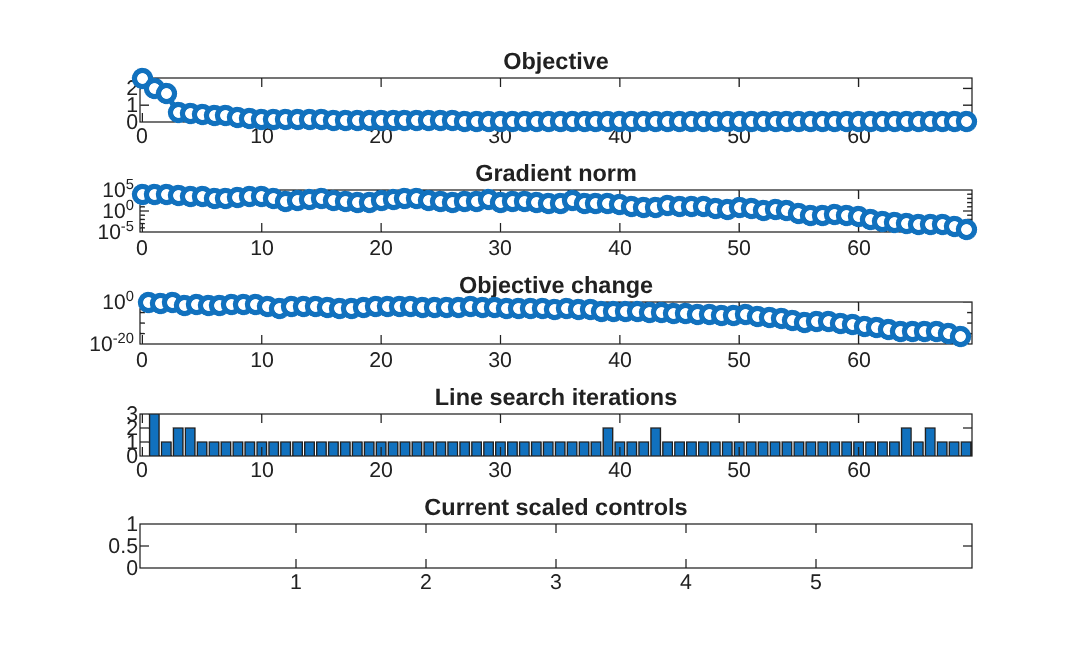

Stopped because reached objChangeTol = 1.000000e-15.
 50 % discharge...
Solving timestep 01/10:              -> 180 Seconds
Solving timestep 02/10: 180 Seconds  -> 360 Seconds
Solving timestep 03/10: 360 Seconds  -> 540 Seconds
Solving timestep 04/10: 540 Seconds  -> 720 Seconds
Solving timestep 05/10: 720 Seconds  -> 900 Seconds
Solving timestep 06/10: 900 Seconds  -> 1080 Seconds
Solving timestep 07/10: 1080 Seconds -> 1260 Seconds
Solving timestep 08/10: 1260 Seconds -> 1440 Seconds
Solving timestep 09/10: 1440 Seconds -> 1620 Seconds
Solving timestep 10/10: 1620 Seconds -> 1800 Seconds
*** Simulation complete. Solved 10 control steps in 797 Milliseconds ***
 1 min pause...
Solving timestep 1/5:            -> 12 Seconds
Solving timestep 2/5: 12 Seconds -> 24 Seconds
Solving timestep 3/5: 24 Seconds -> 36 Seconds
Solving timestep 4/5: 36 Seconds -> 48 Seconds
Solving timestep 5/5: 48 Seconds -> 60 Seconds
*** Simulation complete. Solved 5 control steps in 357 Milliseconds ***


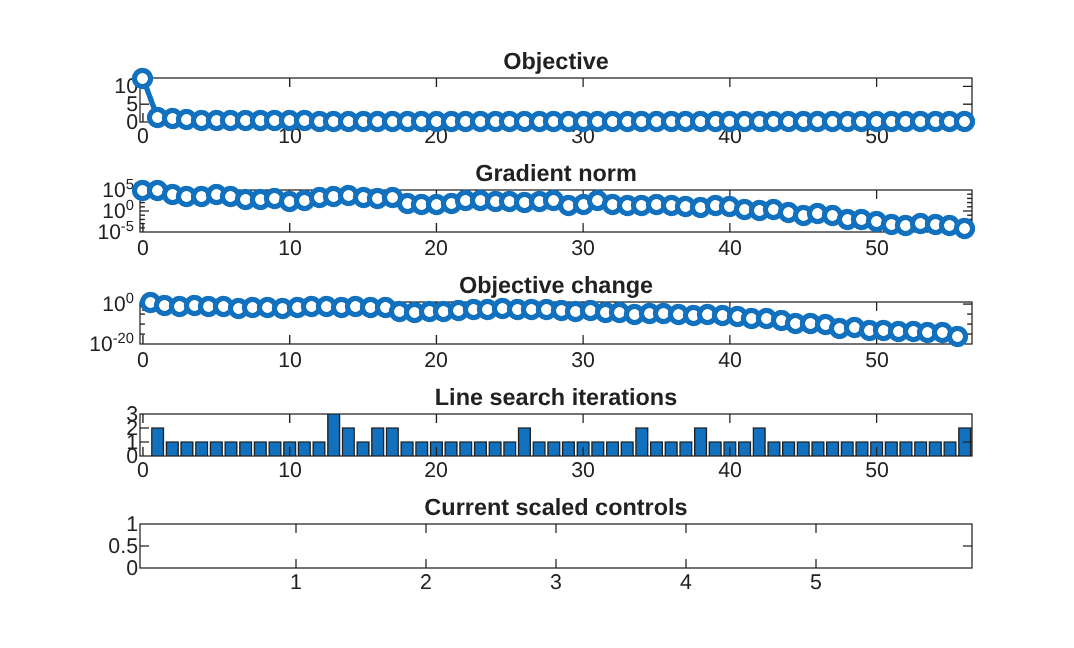

Stopped because reached objChangeTol = 1.000000e-15.
    SOC       R0         R1       C1         R2         C2  
    ___    ________    ______    _____    ________    ______

    0.5    0.032452    6.0577    36206      0.0144    3597.1
      1    0.045339    13.785    24495    0.018915    3215.2

jsonstruct_ecm structure saved successfully in: jsonstruct_ecm_calibrated_50.mat


jsonstruct_material = parseBattmoJson(fullfile('ParameterData','ParameterSets','Chen2020','chen2020_lithium_ion_battery.json'));
jsonstruct_geometry = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'geometryChen.json'));

jsonstruct_p2d = mergeStructs({jsonstruct_material, ...
                                   jsonstruct_geometry});
   
jsonstruct = calibrateEcmFromP2D(jsonstruct_p2d, soc_step);

plot the results

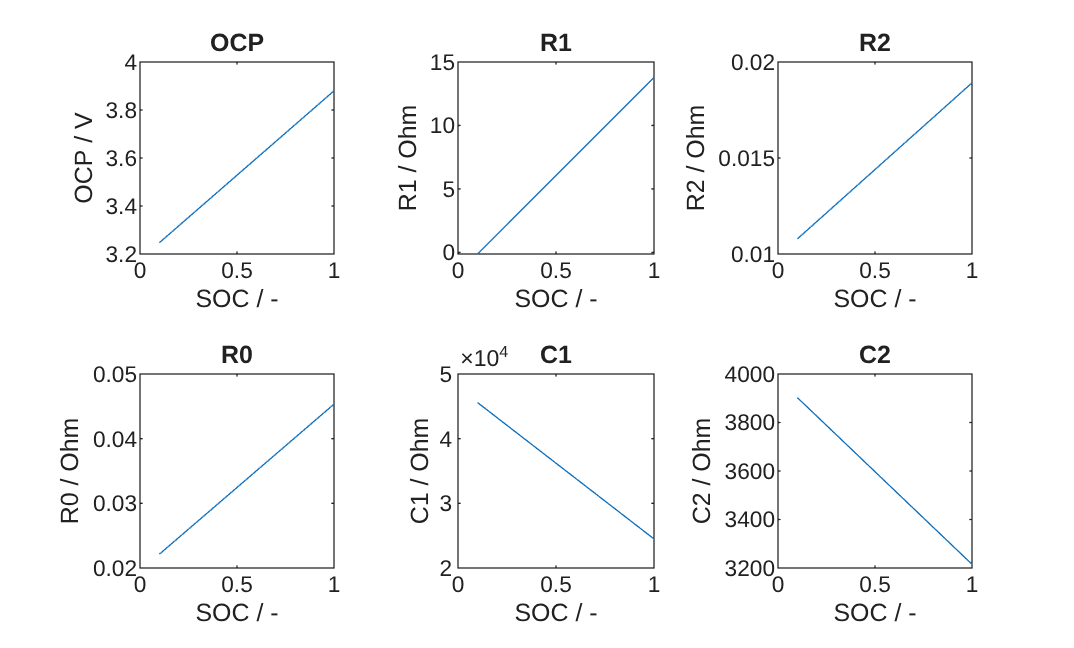

soc = linspace(0.1, 1.0, 100);
figure
tiledlayout(2, 3, 'tileindexing', 'columnmajor');

nexttile

% the function |setupFunction| creates a function handle from the battmo function input format.
fn = setupFunction(jsonstruct.OCP);
plot(soc, fn(soc))
title('OCP')
xlabel('SOC / -')
ylabel('OCP / V');

nexttile
fn = setupFunction(jsonstruct.R0);
plot(soc, fn(soc))
title('R0')
xlabel('SOC / -')
ylabel('R0 / Ohm');

nexttile
fn = setupFunction(jsonstruct.R1);
plot(soc, fn(soc))
title('R1')
xlabel('SOC / -')
ylabel('R1 / Ohm');

nexttile
fn = setupFunction(jsonstruct.C1);
plot(soc, fn(soc))
title('C1')
xlabel('SOC / -')
ylabel('C1 / Ohm');

nexttile
fn = setupFunction(jsonstruct.R2);
plot(soc, fn(soc))
title('R2')
xlabel('SOC / -')
ylabel('R2 / Ohm');

nexttile
fn = setupFunction(jsonstruct.C2);
plot(soc, fn(soc))
title('C2')
xlabel('SOC / -')
ylabel('C2 / Ohm');